# Course 2 Quiz 1

## Working with Test Patterns

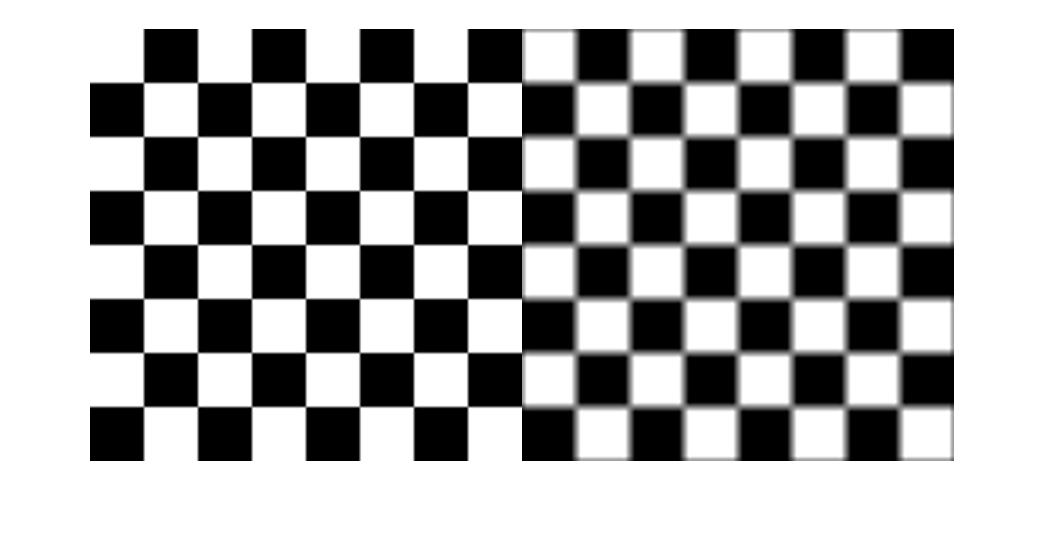

A = ones(16);
B = zeros(16);
C = [A, B; B, A];
C = [C, C; C, C];
img = [C, C; C, C];

AvgF = fspecial("average", 3);
imgAvg = imfilter(img, AvgF);
montage({img, imgAvg})

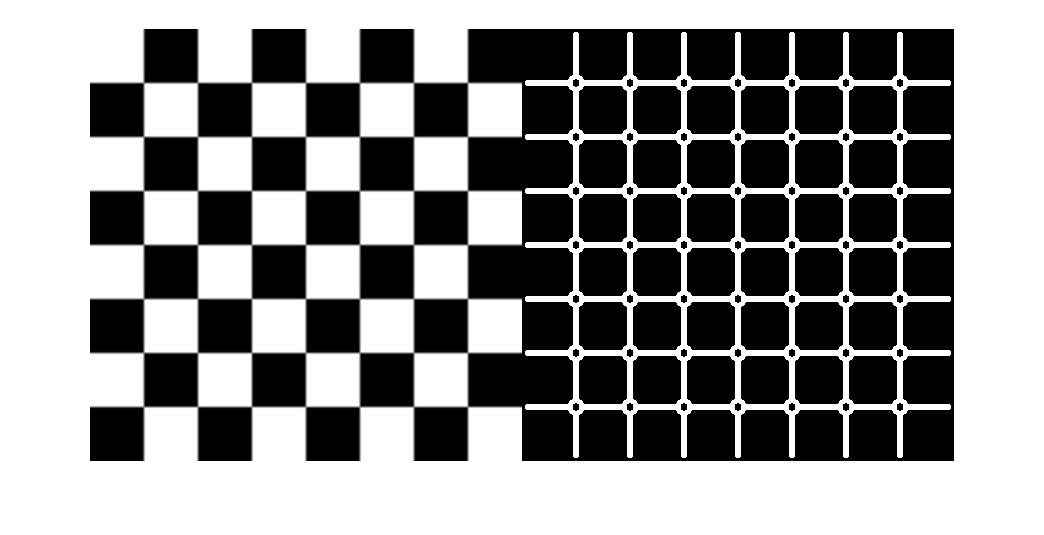

imgEdge = edge(img, "canny");
montage({img, imgEdge})

## Visualizing Gradients

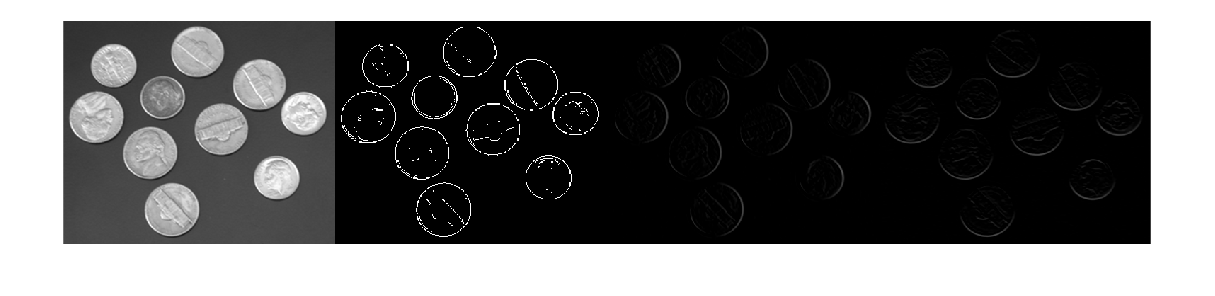

imgC = imread("coins.png");
[imgCEdge, threshOut, vertEdgeGrad, horzEdgeGrad] = edge(imgC, "sobel");
montage({imgC, imgCEdge, vertEdgeGrad, horzEdgeGrad}, "Size", [1 4])

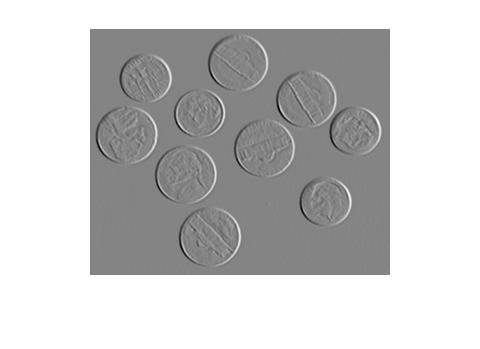

imshow(vertEdgeGrad, [])

## Detecting Edges in Coins

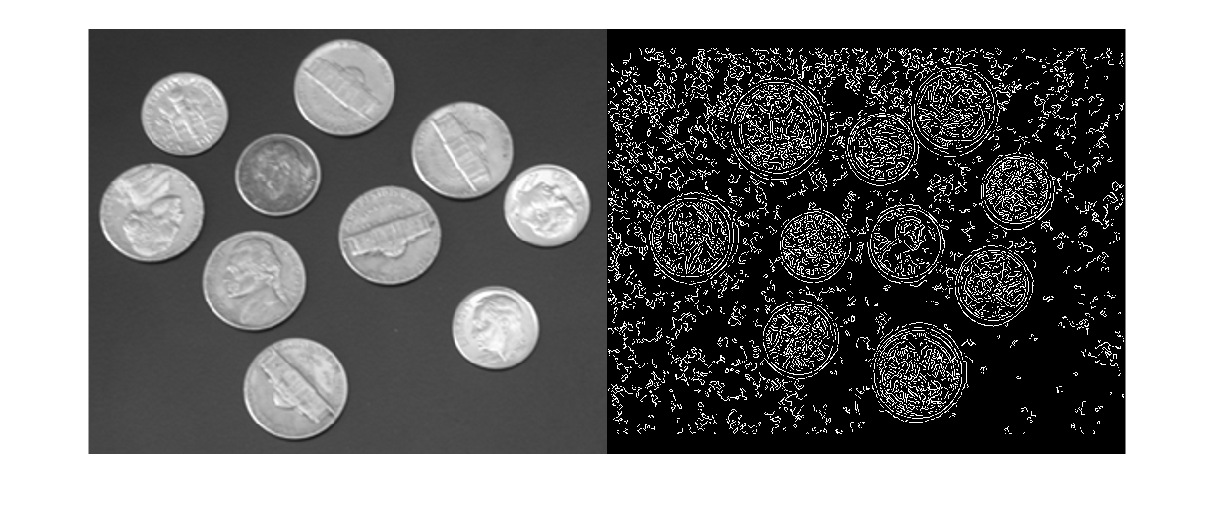

imgC1 = imread("coins1.jpg");
imgC1 = imresize(imgC1, 0.25);
imgC1Edge = edge(imgC1, "canny");
montage({imgC, imgC1Edge})

## Counting Coins 1

imgC3 = imread("coins3.jpg");
imgC3 = imresize(imgC3, 0.25);
imgC3F = imgaussfilt(imgC3, 1);
[centers, radii] = imfindcircles(imgC3F, [60 80]);
radii

radii =    63.9615
   62.0275
   63.3786
   69.8817


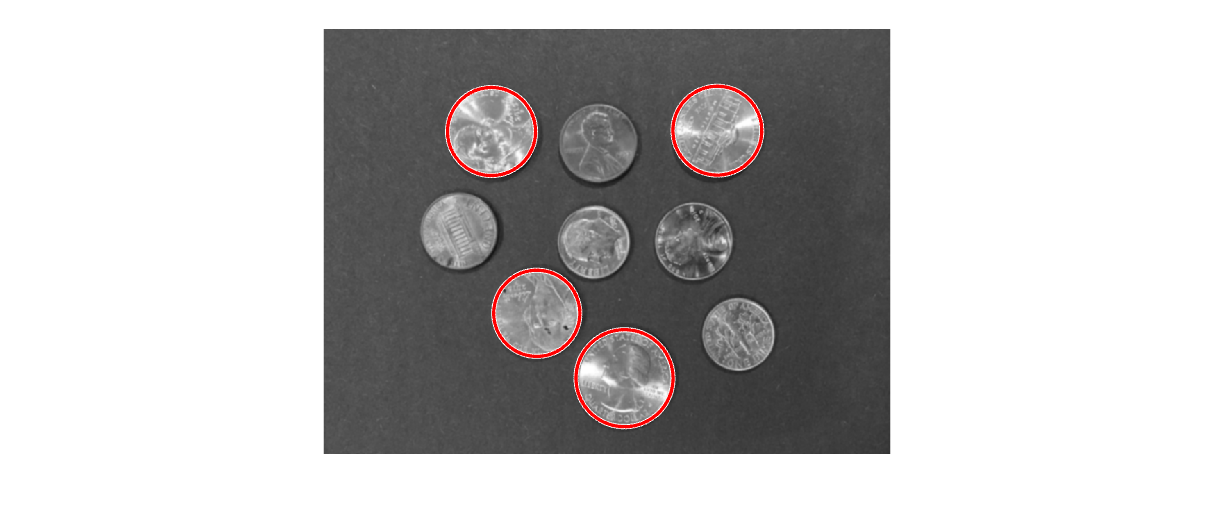

imshow(imgC3F)
viscircles(centers, radii);

## Counting Coins 2

imgC2 = imread("coins2.jpg");
imgC2 = imresize(imgC2, 0.37);
imgC2F = imgaussfilt(imgC2, 1);
[centers2, radii2] = imfindcircles(imgC2F, [40 100]);
radii2

radii2 =    76.0288
   75.5984
   82.8398
   91.9413
   92.4736
   77.4274
   91.3732
   82.5516


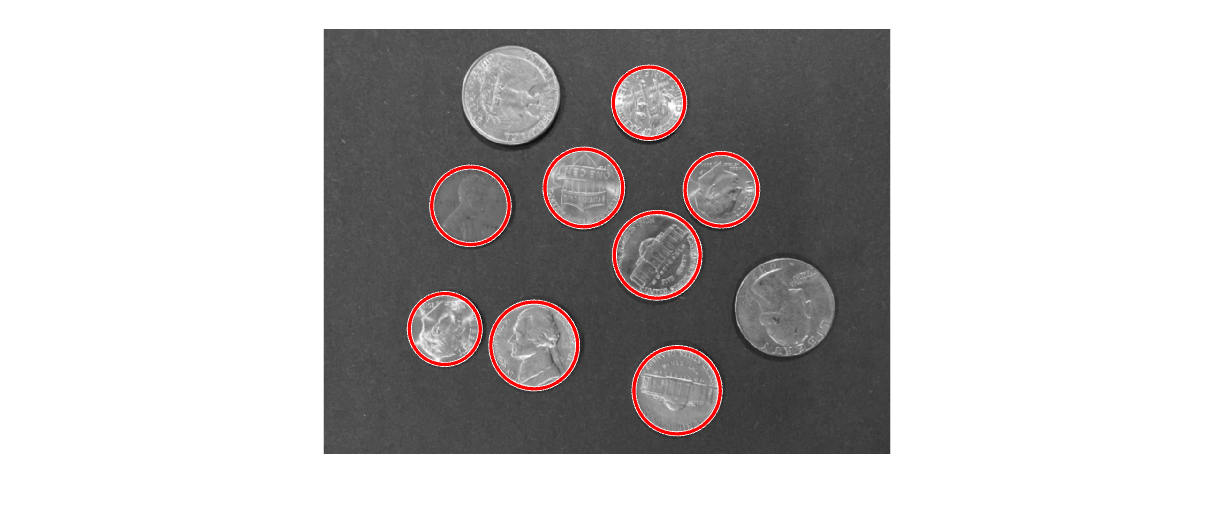

imshow(imgC2F)
viscircles(centers2, radii2);